# Platform path finding using APF

## 2D grid

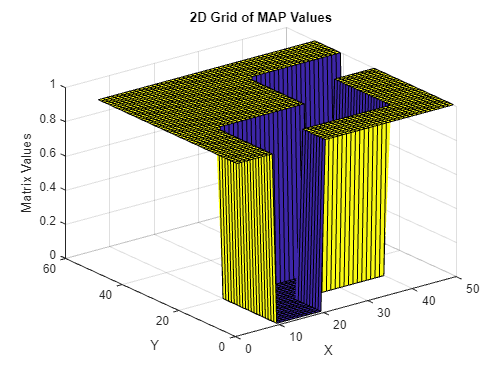

grid = ones(50,50);
grid(10:20,1:20) = 0;
grid(20:40, 10:20) = 0;
grid(30:40, 20:40) = 0;
grid(40:50, 30:40) = 0;

% Create a 2D grid using meshgrid
[X, Y] = meshgrid(1:50, 1:50);

% Plot the 2D grid with the matrix values
figure
surf(Y, X, grid)
xlabel('X')
ylabel('Y')
zlabel('Matrix Values')
title('2D Grid of MAP Values')

% colorbar

## Repulsive APF - Convolution

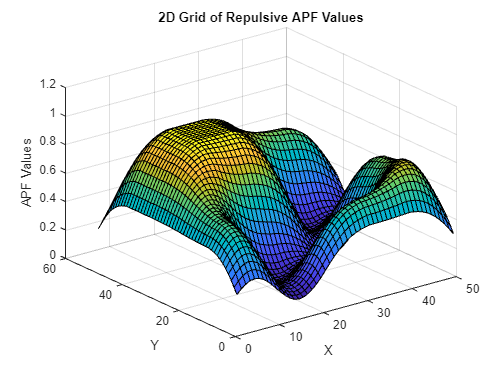

% Set the standard deviation for the Gaussian filter
sigma = 5;

% Define the size of the filter
filterSize = 2 * ceil(2*sigma) + 1;

% Create a grid
[X, Y] = meshgrid(-(filterSize-1)/2 : (filterSize-1)/2);

% Create the Gaussian filter
gaussFilter = exp(-(X.^2 + Y.^2) / (2*sigma^2));
gaussFilter = gaussFilter / sum(gaussFilter(:));  % Normalize the filter

% Convolve the input matrix with the Gaussian filter
repulsive_field = conv2(grid, gaussFilter, 'same');


% Create a 2D grid using meshgrid
[X, Y] = meshgrid(1:50, 1:50);

% Plot the 2D grid with the matrix values
figure
surf(Y, X, repulsive_field)
xlabel('X')
ylabel('Y')
zlabel('APF Values')
title('2D Grid of Repulsive APF Values')

## Attractive APF

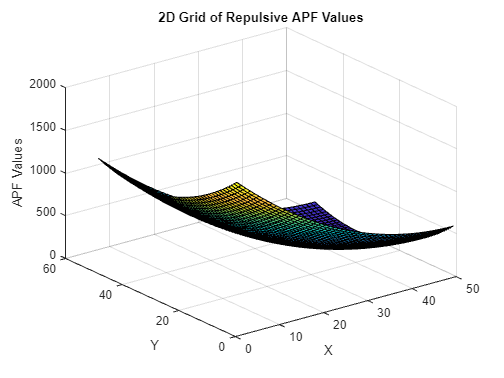

% a 1x2 vector that represents the goal cell (row, column).
goal = [50,35];

% Initialize the matrix to store the attractive potential field.
attractive_field = zeros(size(grid));

% Iterate through every cell in the 2D matrix.
for row = 1:size(grid,1)
    for col = 1:size(grid,2)
        % Calculate the Euclidean distance from each cell to the goal.
        distance = sqrt((row-goal(1))^2 + (col-goal(2))^2);

        % Calculate the attractive potential field for the current cell.
        attractive_field(row, col) = 0.5 * distance^2;
    end
end

% Create a 2D grid using meshgrid
[X, Y] = meshgrid(1:50, 1:50);

% Plot the 2D grid with the matrix values
figure
surf(Y, X, attractive_field)
xlabel('X')
ylabel('Y')
zlabel('APF Values')
title('2D Grid of Repulsive APF Values')

## Attractive + Repulsive APF

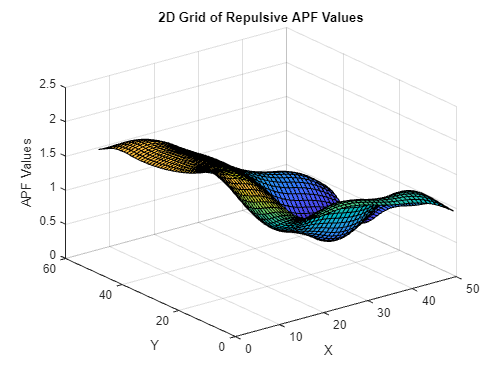

sum_field = attractive_field/max(attractive_field(:))*2 + repulsive_field;

% Create a 2D grid using meshgrid
[X, Y] = meshgrid(1:50, 1:50);

% Plot the 2D grid with the matrix values
figure
surf(Y, X, sum_field)
xlabel('X')
ylabel('Y')
zlabel('APF Values')
title('2D Grid of Repulsive APF Values')

## Path

% gradient kernel - Sobel
kernel = [sqrt(2)  sqrt(8)  sqrt(2);
          sqrt(5)     0     sqrt(5);
          sqrt(2)  sqrt(8)  sqrt(2)];


% set starting point
startLocation = [15,15];

path = [startLocation];

for i = 1:1:50
    
    % Current location
    currentLocation = path(end,:);

    % Perform convolution
    result = conv2(sum_field(startLocation(1)-1:startLocation(1)+1,startLocation(2)-1:startLocation(2)+1), kernel, 'same');
    
    % Find the minimum value
    [minValue, minIndex] = min(result(:));
    
    % Convert the index to row and column coordinates
    [minRow, minCol] = ind2sub(size(result), minIndex);

    % Display the result
    disp("Lowest point found at:");
    disp("Row: " + minRow);
    disp("Column: " + minCol);

    path = [path ; [currentLocation(1)+minRow-2 currentLocation(1)+minCol-2 ]]

end

Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


Lowest point found at:


Row: 3


Column: 1


path =     15    15
    16    14
    17    15
    18    16
    19    17
    20    18
    21    19
    22    20
    23    21
    24    22


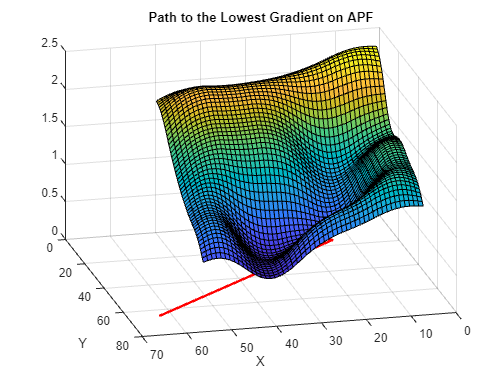

% Create a new figure
figure

% Plot the attractive potential field as a surface
surf(sum_field)
hold on

% Plot the path on top of the surface
plot(path(:,2), path(:,1), 'r', 'LineWidth', 2)

% Adjust the view angle
view(0, 90)

% Set the labels and the title
xlabel('X')
ylabel('Y')
title('Path to the Lowest Gradient on APF')